通过此函数判断颗粒反应时长。

**反应时长判断的前提如下：**

    1、反应时长通过反应截止时间减去反应开始时间。

    2、反应开始时间通过手动点击选取。对于同一个视野中的颗粒，**假设含有氧化剂的溶液充满腔室后反应即开始发生，且视野中的颗粒同时发生反应。**这一假设可能有些强，但作为一个零阶近似是可以接受的，且观察各颗粒的强度走势可知，这个假设也是合理的。

    3、各个颗粒反应结束的时间各自不同，这是通过判断条件自动判断的。其方法是：对单颗粒强度曲线进行归一化之后进行平滑，随后将颗粒强度降低至0.05以下作为反应结束的判断标准。对于部分颗粒，其强度将至0.05以下后可能还伴随有强度的上升，对于这些非典型颗粒，将通过手动判断的方法确定其反应结束时间。

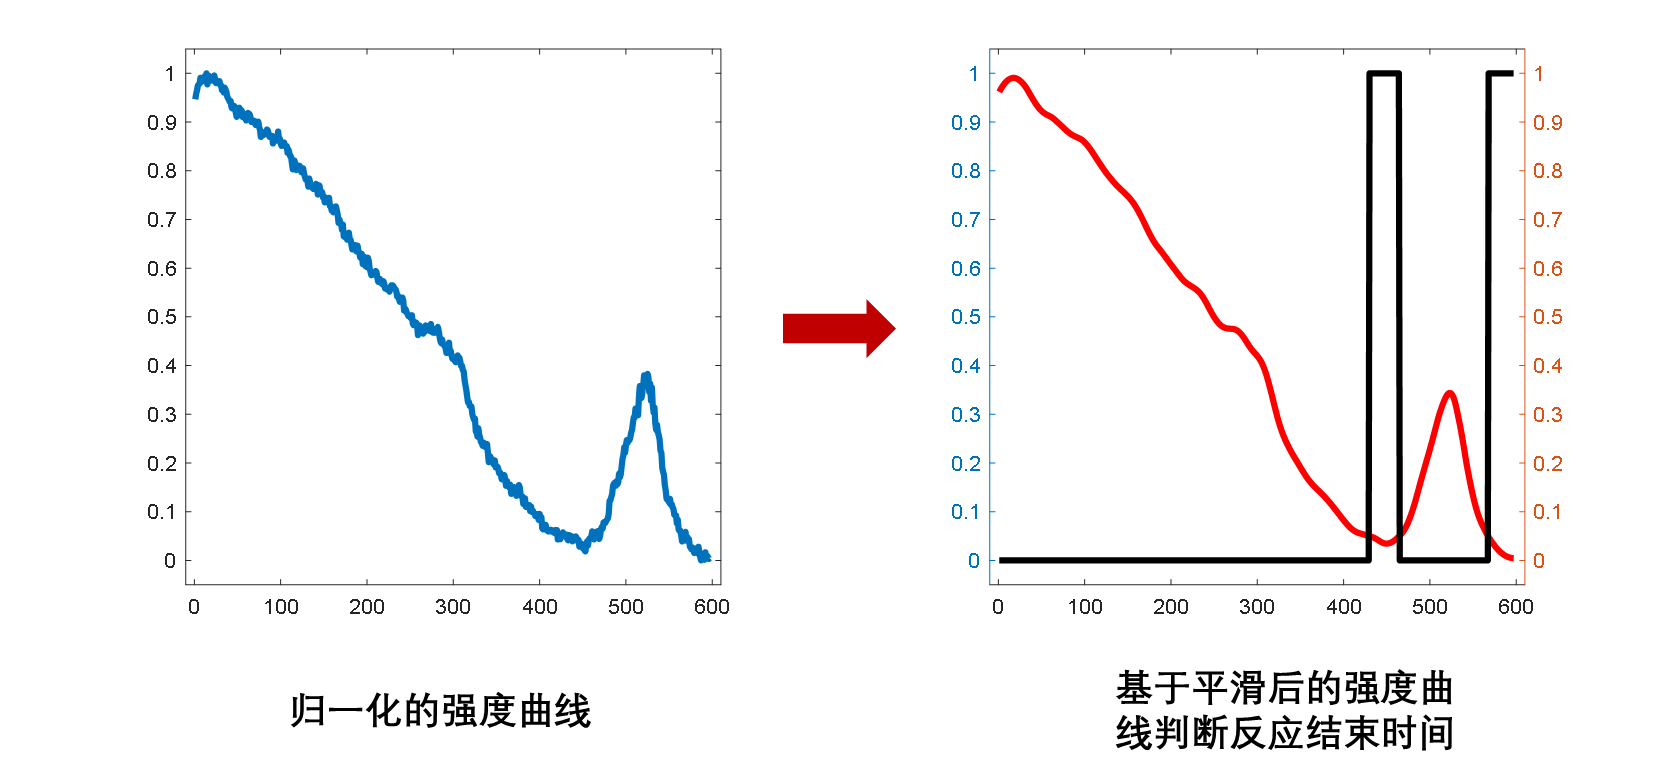

function reaction_Time(result_path)

    files = dir(result_path);
    files(1:2) = [];

% ------------------- 手动选择开始反应的时刻 ----------------------
    start_time = zeros(length(files),1);
    for ii = 1:length(files)
        IJ_path = fullfile(result_path, files(ii).name);
        temp = load(fullfile(IJ_path, 'IJ.mat'));   field = fields(temp);
        IJ = temp.(field{1});
        figure
        plot(sum(squeeze(IJ.Intensities(:,3,:)),2))     % 减掉背景的颗粒信号做平均，因为有时候背景确实糟糕
        title(files(ii).name)
        [x, ~] = ginput(); close
        start_time(ii) = x;
    end

% ------------------ 自动判断结束时间 --------------------------
    for ii = 1:length(files)
        % ------------------ 初始化 -------------------
        IJ_path = fullfile(result_path, files(ii).name);
        savepath = fullfile(IJ_path, '反应始末时间数据');
        if ~exist(savepath, 'dir'); mkdir(savepath); end
        temp = load(fullfile(IJ_path, 'IJ.mat'));   field = fields(temp);
        IJ = temp.(field{1});
        Intensities = IJ.Intensities;
        time_step = IJ.info.increment/IJ.info.fps;      % 时间间隔
        % ---------------- 反应始末时间 ------------------
        BET = zeros(size(Intensities,3), 3);            % beginning and end time (BET)
        BET(:,1) = start_time(ii);       % 第一列为反应开始时刻
        for jj = 1:size(Intensities, 3)
            BET = end_time(Intensities, BET, jj, savepath);        % 更新终止时间
        end
        BET(:,3) = diff(BET(:,1:2), 1, 2);      % 第三列是反应结束时刻减去反应开始时刻
        BET = BET*time_step;

        % -------------------- 统计反应时间 ----------------------
        figure('Visible', 'off'); axis square
        histogram(BET(:,3), 8)
        saveas(gcf, fullfile(savepath, '反应时间统计.tif'));
        close

        % ------------------------ 保存数据 -------------------
        IJ.statistics.BET = BET;
        save(fullfile(IJ_path, 'IJ.mat'), 'IJ', '-v7.3');
    end

end


function BET = end_time(I, BET, ind, savepath)  
% END_TIME 判断颗粒反应结束时刻
%
% BET = end_time(I, BET, ind, savepath)
%
% 说明
%   判断方式是将原始数据进行归一化（以第一帧和最后一帧为基准进行归一化），然后以 0.05 为
%   限进行判断，低于此值认为是反应完了。但事实上，部分颗粒存在一些特殊情况：
%       - 虽然对颗粒定位的时候有删选机制，但总不能避免有一些颗粒/误判一些颗粒，这些颗粒不反应，或者根本
%         就不是颗粒，这部分数据需要先判断，然后剔除掉
%       - 出现多段强度低于 0.05 的时间段，
%       - 即便到最后时刻，颗粒也未反应完，这个需要判断，然后将这部分颗粒剔除掉，我们只分析反应完全的颗粒
%   如何判断颗粒是否反应
%       - 对颗粒强度的标准差进行判断，如果此值小于背景标准差的3倍，则认为选择的是背景或者颗粒未反应
%   如何判断颗粒是否反应完全
%       取obj_copy类中的Intensities属性中的第三列，即减去背景的强度。我们各个颗粒在最后一帧的强度进行统
%       计，取标准差，认为最后一帧的强度大于三倍标准差的即属于未反应完，这种颗粒我们剔除掉，将其结束时刻置
%       为 0.
%   对于有多段强度低于 0.05 的颗粒，如何判断其反应结束时间呢
%       这种颗粒，首先通过二值判断，将强度低于 0.05 的区间置为 1，其余置为 0，得到一个一维的二值曲线，随后
%       通过bwlabel函数标记连通域，取最后一个连通域的起始帧作为反应结束时刻
%   
% 输入
%   I - 颗粒强度矩阵，即 obj_copy.Intensities
%   BET - 反应始末矩阵
%   ind - 颗粒序号，即对第 ind 个颗粒进行分析
%   savepath - 保存路径
% 输出
%   BET - 更新的反应始末时间矩阵

% ------------------------ 初始化 -------------------------
    I1 = squeeze(I(:,1,ind));               % 第 ind 个颗粒的强度，不减背景
    I3 = squeeze(I(:,3,:));                 % 这一批次数据中所有颗粒的强度，减掉背景
    
% ------------------------ 判断颗粒数据 ------------------
    p_bg_std = std(squeeze(I3(end,:)));     % 最后一帧颗粒强度的均方根，用此值判断颗粒是否完全反应
    p_std = std(I1);                        % 颗粒不减背景的标准差
    bg_std = std(squeeze(I(:,2,ind)));      % 背景的标准差
    if I3(end, ind) > 3*p_bg_std            % 如果最后一帧的值远大于背景噪声水平，则判断此颗粒未反应完
        BET(ind, 2) = 0;                    
    elseif p_std < 3*bg_std                 % 如果颗粒本身强度变化的标准差不显著大于背景强度波动的标准差，认为此颗粒未反应/是背景
        BET(ind, 2) = -1;
    else
        I = matNormalize(squeeze(I(:,1,ind)));  % 对强度曲线以第一帧和最后一帧为基准进行归一化
        Is = smooth(I, 50);                 % 对强度曲线进行平滑
        Is = matNormalize(Is);              % 对平滑后的强度曲线进行归一化
        temp = Is < 0.2;                   % 判断反应是否结束
        L = bwlabel(temp);
        end_ind = find(L == max(L));        % 所有连通域中最后一个连通域的第一帧认为是反应结束时刻
        BET(ind, 2) = end_ind(1);
        figure('Visible', 'on'); axis square
        plot(I, 'k', 'LineWidth', 1); hold on;
        yyaxis("left"); plot(Is, 'r', 'LineWidth', 1.5)
        scatter(BET(ind,1),I(round(BET(ind,1))),'r*','linewidth',2,'SizeData',50);
        scatter(BET(ind,2),I(round(BET(ind,2))),'b*','linewidth',2,'SizeData',50);
        yyaxis('right'); plot(temp,'b', 'LineWidth', 1.5);
        saveas(gcf, fullfile(savepath, ['Time_' num2str(ind) '.tif']));
        close
    end
end